# RVC 1, Ch 2

clear variables
close all
clc
clear livescript

## Lec 03.6 (Ch 2.2) 3D Rotations

Let's begin by creating a reference world frame that will not move:

W = eye(3)

Poses can easily be visualized with the 'trplot' command. Visualize it in rgb colors and as the world frame {W}

(Learn more about trplot with: `help trplot`(.

trplot(W, 'frame', '{W}', 'view', [45,45], 'color','c') 

Now, let's learn to compute specific 3D rotations. 

Let's start with a rotation about the x-axis in radians of the world frame {W} and call it rx:

rx = rotx(pi/4)

Visualize with `trplot`(). 

Use the Rotate 3D tool to visualize the new 3D frame.

hold on; grid on; % Let's let the figure keep the previous plot
trplot(rx, 'frame', '{rx}', 'view', [45,45], 'color', 'r'); % To learn about all trpolot options call help trplot

*Note how the local frame has been rotated while the world coordinates have not.*

roty: Now, let's introduce a rotation about the y-axis"

ry = roty(45,'deg')

Note: if rotx/roty/rotz do not work when coupled with 'deg', the 'phased' toolbox functions by the same name may be interfering with the robotics toolbox. Remove the 'phased' matlab toolbox or increase the priority of the robotics toolbox in the path. 

Visualize:

trplot(ry, 'frame', '{ry}', 'view', [45,45], 'color', 'g'); % hold on will still be running until it is manually turned of

Finally, a rotation about z:

rz = rotz(45,'deg')

Visualize:

trplot(rz, 'frame', '{rz}', 'view', [45,45], 'color', 'b');

### **Rotation Matrix Properties**

Rotation matrices have very unique properties. Let's look at 4/8:

- **Orthogonal:** A rotation matrix is orthogonal, meaning its rows and columns are mutually orthogonal (perpendicular) to each other. Mathematically, for a rotation matrix RR, RTR=RRT=IRTR=RRT=I, where RTRT is the transpose of RR, and II is the identity matrix.

- **Determinant of 1:** The determinant of a rotation matrix is always 1. This property indicates that the matrix preserves the volume during transformation. It is a key feature distinguishing proper rotation matrices from other orthogonal matrices, whose determinants could be -1 (like in the case of reflection matrices).

- **Preserves Vector Lengths and Angles:** A rotation matrix, when applied to a vector, preserves the length of the vector and the angles between vectors. This property is crucial in applications where maintaining the scale and shape of objects during rotation is necessary.

- **Inverse Equals Transpose:** Due to its orthogonality, the inverse of a rotation matrix is equal to its transpose, i.e., R−1=RTR−1=RT. This property simplifies many calculations, particularly in computer graphics and 3D transformations.

% Property 1: Orthogonality RR' = I
% All rows and columns are perpendicular to each other. If you multiply a rotation matrix with its transpose, you multiply each column with its row.
% This is effectively a dot product, which yields 0 for perpendicular, 1
% with parallel.
rx * rx'
ry * ry'
rz * rz'

**Property 2**: det(R) = 1. 

I.e. imagine rotating a cube. This rotation applied to each point, would not change the size/volume of the object.

det(rx)
det(ry)
det(rz)

**Property 4**: 

The inverse of R is equal to the transpose of R

rx'
inv(rx)

% You can also run this equality test:
tolerance = 1e-10;
all(abs(rx' - inv(rx)) < tolerance, 'all')

#### Converting Rotation matrices to Homogeneous Transform Matrices

If you need to convert your rotation matrix (3x3) to a homogeneous transform matrix (4x4), use the **r2t** function:

size(rx)
T = r2t(rx)

You can also achieve this directly with the command trotx (and troty, trotz)

T = trotx(pi/2)
T = trotx(90, 'deg')

## Lec 02.7 (Ch 2.2) 3D Rotations

The next set of properties for us to examine are:

- **Concatenation of Rotations:** Multiple rotations can be concatenated into a single rotation matrix through matrix multiplication. This composite rotation matrix then represents the cumulative effect of the individual rotations.

- **Rotations in 3D Space:** In three-dimensional space, rotation matrices are 3x3 matrices. They can represent rotations around the principal axes (x, y, z) or any arbitrary axis.

- **Non-commutative:** The multiplication of rotation matrices is generally non-commutative, meaning R1R2≠R2R1 for two rotation matrices R1 and R2. The order of applying rotations significantly affects the final result.

**Property 5**: compounding rotations. 

Set a world frame:

W = eye(3);

Create a compound rotation about the x and y axis:

rx = rotx(pi/4);
ry = roty(pi/4);
rxy = rx*ry

Can you visualize it in your head?

Let's visualize this alongside the world coordinate frame {W} from before:

clf; % clear the old figure

% Plot W
trplot(W, 'frame', '{W}', 'view', [45,45], 'color','c') 

% Plot rxy
hold on;
trplot(rxy, 'frame', '{rxy}', 'view', [45,45], 'color', 'r') 

Notice how we first apply the rx rotation. Then from the new y axis, we apply the rotation about y by 45 degrees!

This by the way is called post-multiplication. We always use the latest frame to apply the new rotation/transformation when we multiply from the right.

**Property 6:** 3D rotations (cardinal or arbitrary axes)

By combining the two rotation operations from before, we are effectively creating an arbitrary rotation:

**Property 7:** Rotations are not commutative $Rx*Ry \neq Ry*Rx$. 

% Reverse Rxy. Should be different:
Rxz = rotx(pi/2)*rotz(pi/2)
Rzx = rotz(pi/2)*rotx(pi/2)

Visualize it:

trplot(Rzx, 'color', 'r', 'frame', 'A', 'view', [45,45],'rgb');

Do an equality test:

tolerance = 1e-10;
all(abs(Rxz - Rzx) < tolerance, 'all')

## Lec 02.8 (Ch 2.2) Euler-Angles

There are two formalisms by which to create compound operations: (i) Euler angles and (ii) RPY rotations. Both of them indicate the order of rotations. However, each one must always clarify what axis are connected to what rotations.

**(i) Euler Angles, ZYZ Sequence:**

Consider a 3-compound operation that will rotate about z, then y, then z again:

R0 = eul2r(0.1,0.2,0.3)

Visualize the sequenze:

clf;
trplot(R0, 'color', 'b')

***Side Note: Mappings across rotations. ***

So far we have learned a few rotation operations: compound rotation matrix operations and now euler angle operations. 

It is possible to map between these (and other operations). 

The summary of all mapping functions can be found on *p. 39 of the RVC1 book in Fig. 2.15*. 

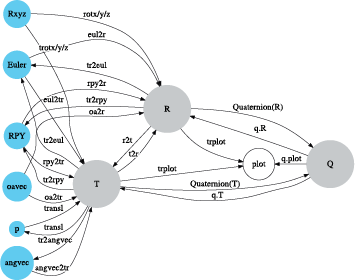

In the case, where we would like to take the resultant rotration matrix from the compound euler rotation and convert it back to a ZYZ sequential euler rotation, you can use 'tr2eul'. 

tr2eul assumes a ZYZ order:

Rzyz = tr2eul(R0)

#### Surjective (2-to-1 Mappings):

Unfortunately, this mathematical representation for rotation, has a weakness. Let's explore it further:

Let's assume a similar ZYZ sequence as before, but this time, let's invert the Y angle and make it negative:

Rzyz_1 = 0.1, -0.2, 0.3
R1 = eul2r(0.1,-0.2,0.3)

Now, let's convert the rotation matrix back to an ZYZ Euler sequence. 

We would expect to recover a ZYZ sequence of 0.1, -0.2, 0.3 angles...

Rzyz_2 = tr2eul(R1)

Indeed, the answer is different. The result states that both:

- Rzyz_1 = 0.1, -0.2, 0.3

- Rzyz_2 = -3.0146, 0.2, -2.8416

        Result in the ***same*** rotation matrix. In other words, we have two different paths that result in the same pose.

       That is what we call a 2-to-1 (surjective) mapping. 

We have the result R1 from above. Let's compute a rotation R2 matrix from Rzyz_2 and compare:

% This shows that actually there 2 sets of Euler angles which can represent
% the same rotation. To show that, we invert ZYZ and check the rotation
% matrix.
R2 = eul2r(Rzyz_2)

Let's do an equality test:

tolerance = 1e-10;
all(abs(R1 - R2) < tolerance, 'all')

#### (ii) Roll-Pitch-Yaw Angles

RPY angles usually associate: 

- the roll with the x-axis, 

- the pitch with the y-axis, and 

- the yaw with the z-axis (this is the convention of the toolbox). 

*Note: the convention is sometimes flipped and the pitch is the x-axis and the roll the y-axis. So always confirm. *

Let's start by instantiating a rotation matrix formed by the followoing RPY sequence:

R3 = rpy2r(0.1,0.2,0.3)

Question: Is this the same rotation matrix as we got with R0 when we did the ZYZ Euler rotation of 0.1, 0.2, 0.3? 

It should not be. 

We are rotating across different axes... Let's bring it back up.

R0

Using the equality test below we see they are not the same:

tolerance = 1e-10;
all(abs(R0 - R3) < tolerance, 'all')

**RPY Mappings:**

As with Euler angles, we can also map the rotation matrix result to RPY formats:

tr2rpy(R3)

**Gimbal Lock**

As noted in the lecture, there is a situation in which the RPY formalism can lose a degree of freedom. 

Any time that the y-axis is initially rotated by 90 degrees, it aligns with the z-axis gimbal and locks to it. 

This leads to a loss of 1 degree of freedom to express pose. The is called Gimbal Lock. 

Test it:

- Start by rotating about your z-axis. Do the other two gymbals move? 

- Now when you rotate your y-axis by $\pm$90 degrees, the y-axis locks onto the z-axis.

- Move your z-axis again, the how the gymbal associated with the y-axis is locked to it? At this angle, you create a dependency and only have the x-axis and the z-axis to describe rotation.

tripleangle('rpy', 'wait')

## Lec 02.11 (Ch 2.2) Angle Sequences

In this section, we study one last property of rotation matrices:

**Property 8:** The eigenvectors and eigenvalues of a 3D rotation matrix. 

- Eigenvector and axis of rotation: note that eigenvector associated with the real eigenvalue of a rotation matrix corresonds to the axis of rotation of the matrix. Consider any of the compound rotations we did previously. With this method you can automtically extract one single axis of rotation that corresponds to the compound operation. 

- Trace and amount of rotation: the rotation about this axis is computed by the function $trace(R)=1+2cos (\theta)$, where the trace is computed by the sum of the diagonals. In this case, $\theta=cos^{-1} \left( \frac{trace(R)-1}{2} \right)$

- Note that for a typical rotation matrix you will find 3 eigenvalues: a pair of complex conjugates and a real eigenvalue of +1. As mentioned above, the eigenvector corresponding to the eigenvalue of +1 is the axis of rotation.

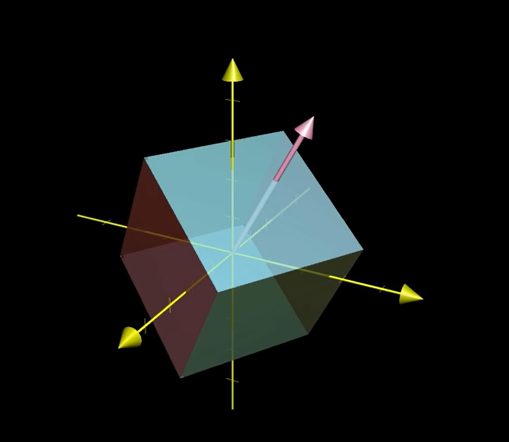

Credit: 3Blue1Brown: Eigenvectors and eigenvalues | Chapter 14, Essence of linear algebra, 2024 Jan  

([https://www.youtube.com/watch?v=PFDu9oVAE-g&t=830s](https://www.youtube.com/watch?v=PFDu9oVAE-g&t=830s))

#### Angle-Axis

% Create a compound rotation matrix using the toolbox function eul2r() and Euler angles of 0.1, 0.2 and 0.3 radians
R = eul2r(pi/2,pi/2,0)

Visualize it:

clf;
trplot(R,'frame', 'A', 'view', [45,45], 'rgb'); % To learn about all trplot options call help trplot

#### **Eigenvectors and Eigenvalues:**

Let us now extract the eigenvectors and the eigenvalues of a rotation matrix using the eig() function. 

Note:

The eigenvectors produced by 3D rotation matrices have 3 column vectors" $\left[ 1 2 3 \right]$. 

Look for the real vector in the cols (i.e. the one that has 0.0000i for all rows).

Use the rotation matrix that we created before and compute the eigenvectors and eigenvalues of that rotation matrix:

[eigVec,eigVal]=eig(R);

Note that eigVal is a matrix, but the values sit on the diagonal of the matrix. 

We extract these three values as:

diag(eigVal)

We see that the last one is in fact the eigenvalue with a real value.

For eigVec, we have three col vectors inside the matrix:

eigVec

In effect, it is the third column that is the axis of rotation:

display( eigVec(:,3) )

The robotics toolbox has a built-in function that not only gives us the single axis of rotation from the eigenvector, but also the correct rotation about that axis. 

You can use the command **tr2angvec() **and assign the output to a $\theta$-rotation and a rotation axis defined by a vector val=[x y z]:

[th,vec]=tr2angvec(R)

Try other simpler values to get a better intuition:

rotx by 90 degrees. What do you expect to get?

[th,vec]=tr2angvec( rotx(pi/2) )

roty by 90 degrees. What do you expect to get?

[th,vec]=tr2angvec( roty(pi/2) )

rotz by 90 degrees. What do you expect to get?

[th,vec]=tr2angvec( rotz(pi/2) )

### Obtaining the Rotation matrix via the Rodrigues Equation:

Mapping operations from angle-axis result to a rotation matrix is also possible:

angvec2r(th,vec)

## Lec 02.12 (Ch 2.2) Unit Quaternions

Before you move to deep into exercises, work on the interactive tutorial on [Quaternions](https://en.wikipedia.org/wiki/Quaternion) below by Ben Eater and Grant Sandersons Collaboration: [https://eater.net/quaternions](https://eater.net/quaternions)

It covers:

- Quaternion intuition: "quaternion multiplication can be understood by looking at how it transforms four-dimensional space."

-     Stereographic projections (mappting higher dimensions to lower dimensions)

-         2D Circles to 1D lines

-         3D Spheres to 2D space

-         4D hyperspheres to 3D space

-     Quaternion Multiplication

-     Unit Quaternions

Let me brifely share some insights for 2D/4D stereoscopic projections: [https://eater.net/quaternions/video/quatmult](https://eater.net/quaternions/video/quatmult) 

Pratically, we use quaternions to describe 3D rotations because they allow for faster computations while providing more robust results. 

### Unit Quaternion Instantiation

Let's learn how to instantiate Unit Quaternions. 

% Create an identity rotation matrix
R0 = eye(3)

Convert the 3x3 rotation matrix into a UnitQuaternion using the UnitQuaternion class and yielding a UnitQuaternion object:

q0 = UnitQuaternion(R0)

Notice the 4D object with a real number in front q.s and a vector following. You can even extract these parts directly with q0.s and q0.v

% Extract the real number:
q0.s

% Extract the vector:
q0.v

Let's now try instantiating a few more with simple rotations about x (can also do it with rpy angles and euler angles):

Rz90  = rotz(pi/2);
Rz180 = rotz(pi);

Convert to UnitQuaternions:

q90 = UnitQuaternion(Rz90)

q180=UnitQuaternion(Rz180)

#### Instantiating Directly with s,v

If you have a real number *s* and a vector *v, * you can instantiate directly:

s = sqrt(2)/2;
v = [0,0,s];
q90 = UnitQuaternion(s,v)

We can use the `animate()` method to animate the transformation from the reference frame to this transformation. 

q90.animate % May not animate in the notebook, but run directly in command window.

### Relationship between angle-axis and UnitQuaternions

In the slides we established that the UnitQuaternion scalar s is: $s=cos \frac{\theta}{2}$ and the complex vector v is: $$v = \hat{n} sin \frac{\theta}{2}$$. 

Let's create an angle-axis representation, and then see what the quaternion looks like:

 Let's look at the angle-axis representation of a 90 degree rotation about the x-axis:

[th,vec]=tr2angvec( rotx(pi/2) )

For quaternions, we will want to compute the cosine and sine of 90 degrees dividied by 2: 

And note that because we are rotating about the x-axis then $$ \hat{n} = [1,0,0]$$

cos(pi/4)
sin(pi/4)
UnitQuaternion (rotx(pi/2) )

Is the result intuitive?

What if we did a rotation by x of 180 degrees?

The angle-vector representation yields:

[th,vec]=tr2angvec( rotx(pi) )

And the quaternion equivalent would be:

cos(pi/2)
sin(pi/2)
UnitQuaternion (rotx(pi) )

### Compounding UnitQuaternion Multiplication

When we use the multiplication operations between UnitQuaternions we are compounding rotation. 

If we multiply q90 with itself, we should get a 180 degrees rotation as with q180.

q180_2 = q90*q90

And we can then reconvert this result to other rotation mappings.

- To a rotation matrix with the R method:

q180_2.R

And we can plot it:

q180_2.plot

Or animate it:

q180_2.animate % May not animate in the notebook, but run directly in command window.

R0 =      1     0     0
     0     1     0
     0     0     1


Also note that the conjugate of the UnitQuaternion is effectively an inverse rotation. 

Multiplying q90 with its inverse will yield the unit (or trivial) quaternion:

q90*q90.conj

 
q0 = 
 
1 < 0, 0, 0 >
 


Note, that no matter what rotation operation, the UnitQuaternion will always have a norm of 1:

q90.norm

ans = 1

q180.norm

Finally, you can convert to other types:

q90.SE3

ans =      0     0     0


q90.toangvec

q90.toeul

q90.torpy

 
q90 = 
 
0.70711 < 0, 0, 0.70711 >
 


q90.T % converts to a homogeneous transformation

 
q180 = 
 
0 < 0, 0, 1 >
 


#### Quaternion Vector Products

We can also directly apply the transformation to a vector. If we apply our q90 transformation about the z-axis and apply it to a column vector pointing in the x-direction, we should get a y-direction vector:

q90*[1,0,0]'

 
q90 = 
 
0.70711 < 0, 0, 0.70711 >
 


th = 1.5708

vec =      1     0     0


ans = 0.7071

ans = 0.7071

 
ans = 
 
0.70711 < 0.70711, 0, 0 >
 


th = 3.1416

vec =      1     0     0


ans = 6.1232e-17

ans = 1

 
ans = 
 
0 < 1, 0, 0 >
 


 
q180_2 = 
 
0 < 0, 0, 1 >
 


ans =     -1     0     0
     0    -1     0
     0     0     1


 
ans = 
 
1 < 0, 0, 0 >
 


ans = 1

ans = 1

 

ans = 
         0   -1.0000         0         0
    1.0000         0         0         0
         0         0         1         0
         0         0         0         1


Rotation: 1.570796 rad x [0.000000 0.000000 1.000000]


ans =          0         0    1.5708


ans =          0         0    1.5708


ans =    -0.0000   -1.0000         0         0
    1.0000   -0.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


ans =          0
    1.0000
         0


TODO: Composition position/orientation homogeneous trans matrices, only translation vectors, etc.